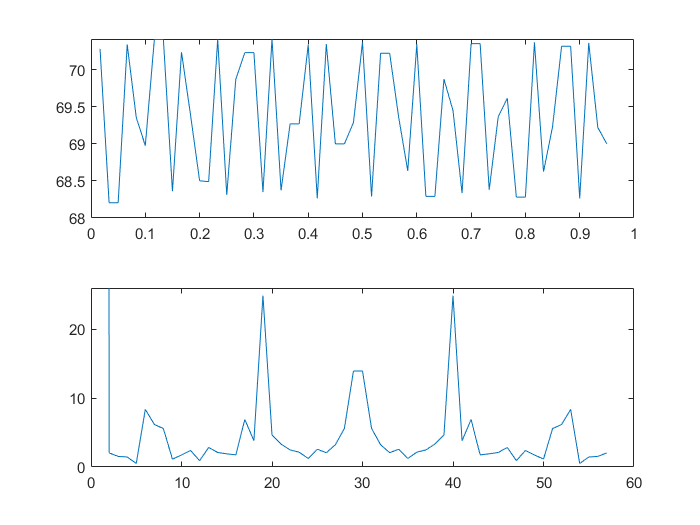

a = VideoReader('cropped.mp4');
k = a.NumFrames ;
Y_Coord = (1:k);
for N = 1:k
    I = readFrame(a);
    %size(I)
    %figure,imshow(I)
    gray_I = rgb2gray(I);
    cropped = gray_I(100:230,430:570);
    %imshow(cropped)
    bw_I = im2bw(cropped,0.52);
    bw_I = ~bw_I;
    %subplot(121), imshow(bw_I)
    bw_I = bwareaopen(bw_I,500);
    %figure, imshow(bw_I)
    %se1 = strel('square',13);
    %se2 = strel('square',13);
    %er = imerode(bw_I,se1);
    %dil = imdilate(er,se1);
    %final = dil(50:350,800:1200);
    %final = bwareaopen(final,1000);
    s = regionprops(bw_I,'Centroid');
    Y_Coord(N) = s.Centroid(1,2);
end
%Y_Coord;
subplot(211),plot((1:k)*1/60,Y_Coord);
ff = fft(Y_Coord);
subplot(212),plot(abs(ff))
ylim([0.0 26.0])